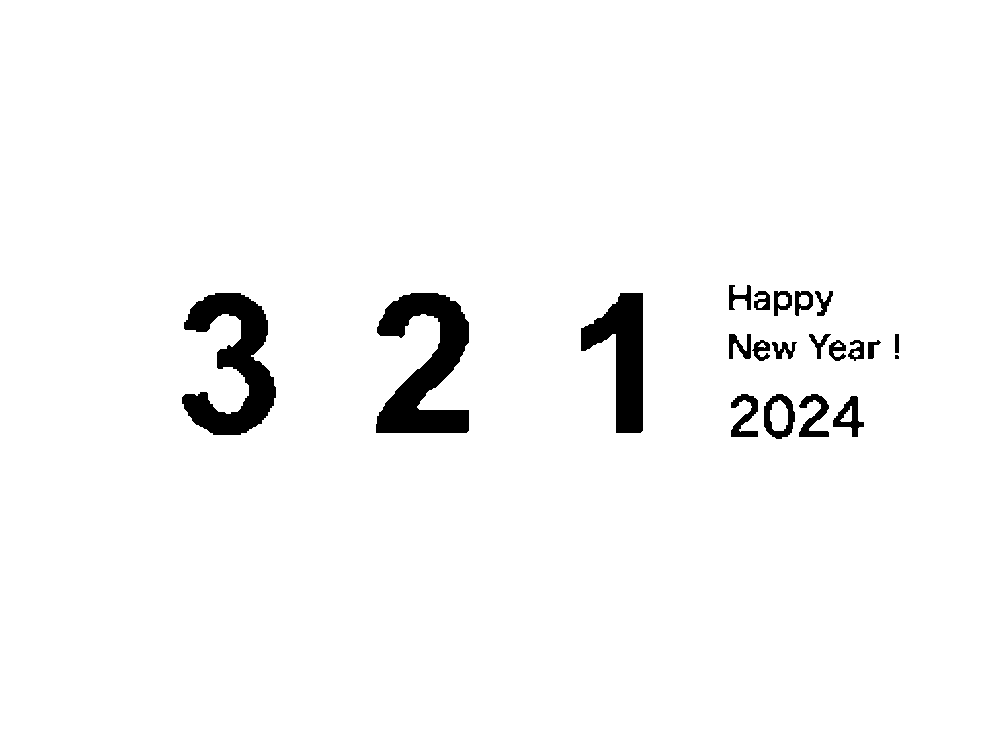

% Get the default image cdata and display 4 images in a rotating cube.

I = get(groot,'defaultimageCData');
defimage = pow2(I,47);

I1 = imread('3.jpg');
I1 = ~imbinarize(I1,0.5);
I2 = imread('2.jpg');
I2 = ~imbinarize(I2,0.5);
I3 = imread('1.jpg');
I3 = ~imbinarize(I3,0.5);
I4 = imread('2024.png');
I4 = ~imbinarize(I4,0.5);

I1 = imresize(I1,[100,100]);
I2 = imresize(I2,[100,100]);
I3 = imresize(I3,[100,100]);
I4 = imresize(I4(:,:,1),[100,100]);


montage([I1,I2,I3,I4])
set(gca,'PositionConstraint','innerposition')

Specify the output file name

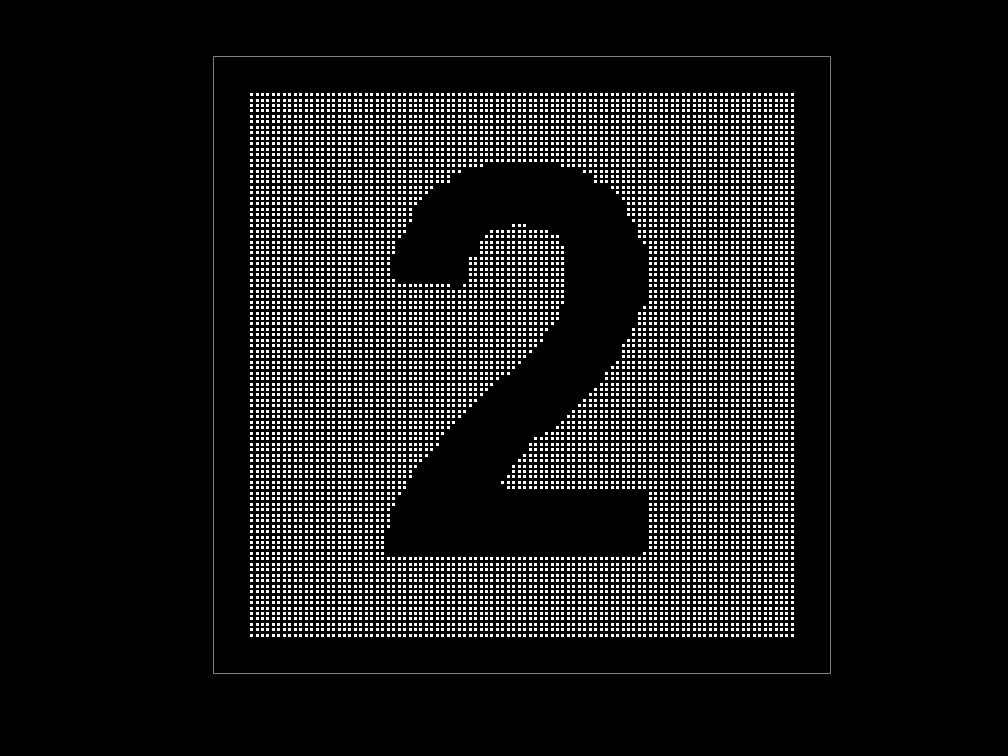

filename = 'HappyNewYear_2024.gif'; 

% Display a transition for each image in sequence.
% I1 => I2
parallaxPlot(I1,I2);

frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
tmp = frame2im(frame); % 画像に変更
[A,map] = rgb2ind(tmp,128); % RGB -> インデックス画像に
imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0.1);
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.2);

pause(1)
for idx=linspace(0,90,25)
    view([ idx (cosd(idx*4)-1)*5 ]);
    drawnow
    frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
    tmp = frame2im(frame); % 画像に変更
    [A,map] = rgb2ind(tmp,128); % RGB -> インデックス画像に
    imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.05);

end

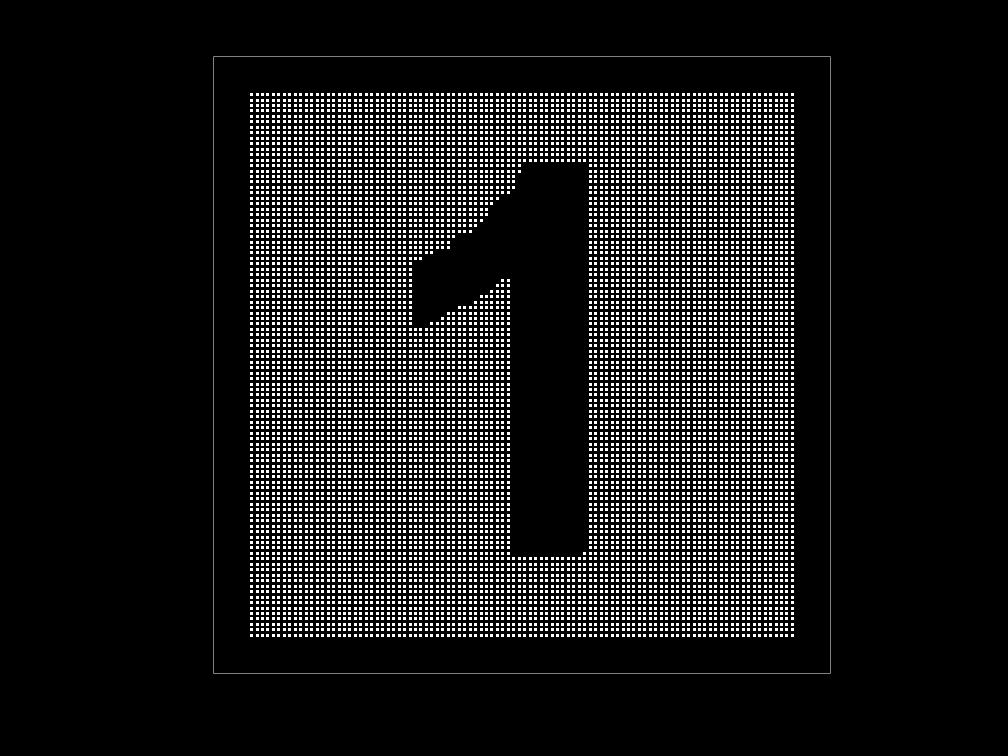


% I2 => I3
parallaxPlot(I2,I3);

pause(1)
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.2);
for idx=linspace(0,90,25)
    view([ idx (cosd(idx*4)-1)*5 ]);
    drawnow
    frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
    tmp = frame2im(frame); % 画像に変更
    [A,map] = rgb2ind(tmp,128); % RGB -> インデックス画像に
    imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.05);

end

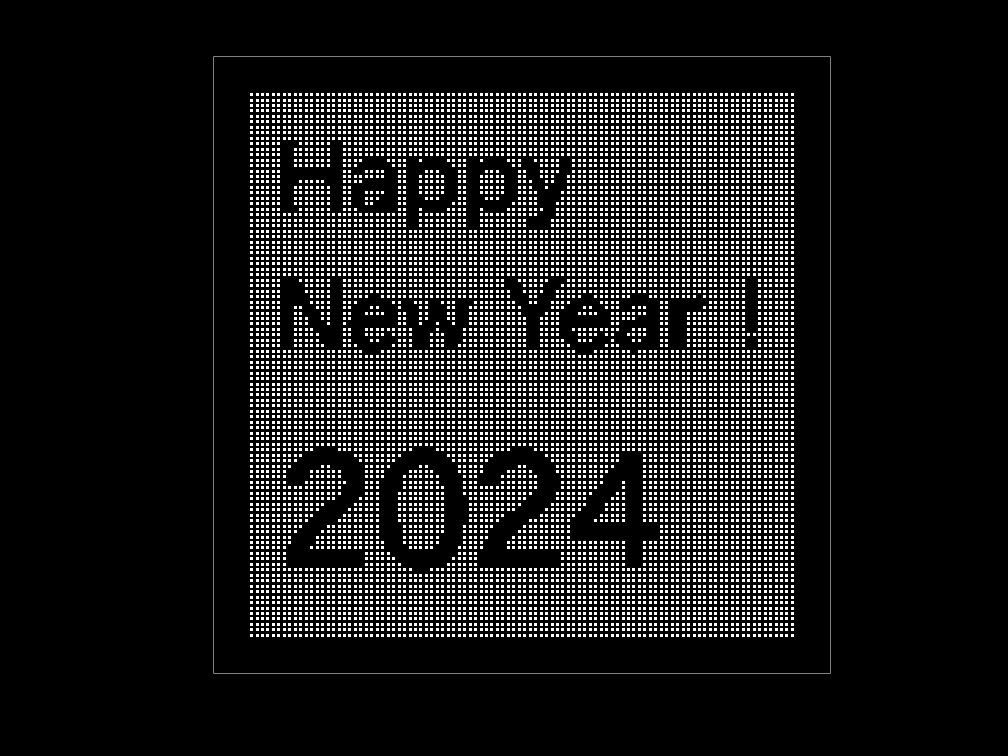


% I3 => I4
parallaxPlot(I3,I4);

pause(1)
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.2);
for idx=linspace(0,90,25)
    view([ idx (cosd(idx*4)-1)*5 ]);
    drawnow
    frame = getframe(gcf); % Figure 画面をムービーフレーム（構造体）としてキャプチャ
    tmp = frame2im(frame); % 画像に変更
    [A,map] = rgb2ind(tmp,128); % RGB -> インデックス画像に
    imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.05);

end


% Pause for 2 secs
pause(1)
imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',2);